clear
clc

system("g++ ./FiniteDifferences.cpp " + ...
    "-O2 -o ./FiniteDifferences.exe -Wall");
N = 500

N = 500

M = N;
system(".\FiniteDifferences.exe " + string(N));

v1.x = round((500 - 68.75)/1000 * N);
v1.y = round(500/1000 * N);
v2.x = round((500 + 68.75)/1000 * N);
v2.y = round(500/1000 * N);

v3.x = round((500 - 68.75)/1000 * N);
v3.y = round((500 + 100)/1000 * N);
v4.x = round((500 + 68.75)/1000 * N);
v4.y = round((500 + 100)/1000 * N);

x = load("x.txt");

ans = -3.5658e-09


DV1 = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))) %[V]

DV1 = 3.7981e-06

DV2 = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))) %[V]

DV2 = 3.3999e-06

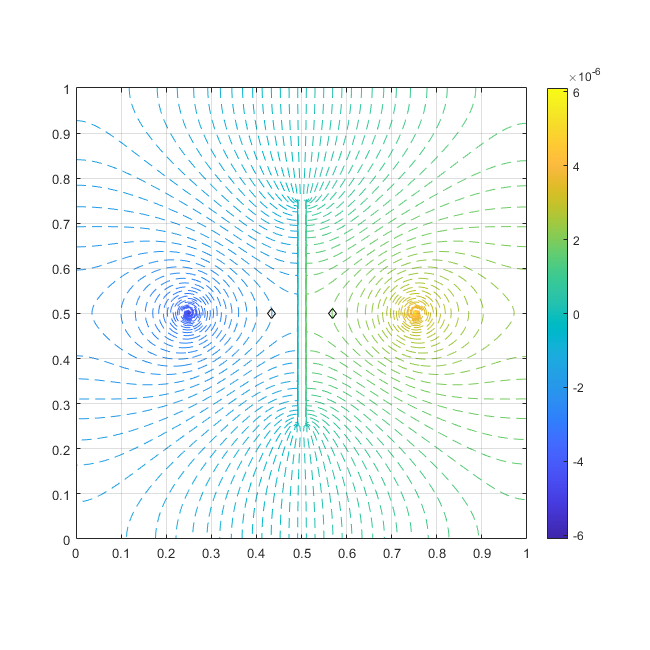

phi = zeros(M,N);
for i = 1:N
    for j = 1:M
        phi(j,i) = x(i + N * (j-1));
%         phi(j,i) = min(phi(j,i), -0.516902);
    end
end

psi = zeros(M,N);
for i = 3:N
    for j = 3:M-1
        psi(j,i) = 1/3 * (4*psi(j-1,i) - psi(j-2,i) + (3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2)));
        psi(j,i) = min(psi(j,i),1e-7);
        psi(j,i) = max(psi(j,i),-1e-7);
    end
end

figure("Position",[0,0,650,650]);
X_range = linspace(0,1,size(phi,2));
Y_range = linspace(0,1,size(phi,1));
Dx = X_range(2) - X_range(1);
Dy = Y_range(2) - Y_range(1);
contour(X_range,Y_range,phi,120,'LineStyle',"--")
hold on
% contour(X_range(3:end),Y_range(3:end),psi(3:end,3:end),300, ...
%     'LineStyle',":",'LineColor','k')
% hold on
scatter(Dx*v1.x,Dy*v1.y,'kd')
scatter(Dx*v2.x,Dy*v2.y,'kd')
xticks(X_range(1) : X_range(end)/10 : X_range(end))
yticks(Y_range(1) : Y_range(end)/10 : Y_range(end))
hold off
grid on
axis equal
colorbar()